与图床边界的距离为0.5个单元长度/宽度

dL = 0.5*abs((Coordinate(Ielement(1,2),1)-Coordinate(Ielement(1,1),1)));
dW = 0.5*abs((Coordinate(Ielement(1,4),2)-Coordinate(Ielement(1,1),2)));

iElement= e.left ;% 绘制的单元编号

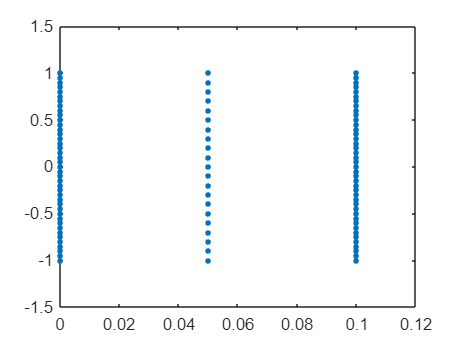

figure
iNodes = Ielement(iElement,:);
iNode = unique(iNodes(:));
plot(Coordinate(iNode,1),Coordinate(iNode,2),'.','MarkerSize',10)

error("按键运行动画")

按键运行动画

动画

 
t = 5e-1; % 动画帧时间
figure()
nodes = Ielement(iElement,:);
plot(nan,nan)
hold on
xlim([min(Coordinate(nodes(:),1)-dL),max(Coordinate(nodes(:),1))+dL]);
ylim([min(Coordinate(nodes(:),2)-dW),max(Coordinate(nodes(:),2))+dW]);

for i = 1:length(iElement)
	draw(iElement(i),t,Ielement,Coordinate)
end
hold off

function draw(iElement,t,Ielement,Coordinate)
% global Ielement Coordinate
ele1 = Ielement(iElement,:);
for i = 1:length(ele1)
	plot(Coordinate(ele1(i),1),Coordinate(ele1(i),2),'.','MarkerSize',10)
	text(Coordinate(ele1(i),1),Coordinate(ele1(i),2),num2str(ele1(i)))
	pause(t)
end
end
